# **Experiência 7 **

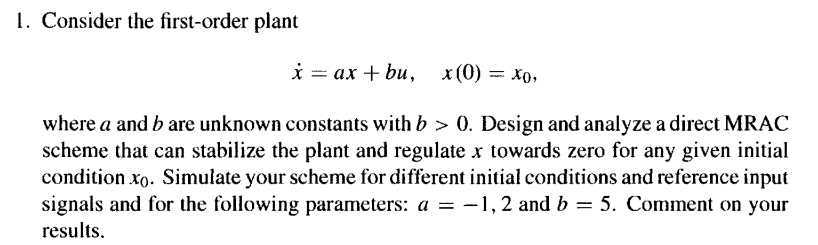

### Condicoes de inicio

    clc;clear;
    dt = 0.01;
    Tfinal = 10;
    t = 0:dt:Tfinal;

### Entrada de referencia

    r = 5*cos(t) + 2*sin(pi*t);

### Parametros da planta modelo

    am = 10;
    bm = 1;

    Ftm = tf(bm,[1 am])

Ftm =
 
    1
  ------
  s + 10
 
Continuous-time transfer function.



    xm = lsim(Ftm,r,t);
    xm(1) = 0;

### Parametros da planta real

    a = 2 ;  % Valores dos polos para o exercício são a = -1 e a = 2

a = 2

    b = 5;

    Ft = tf(b,[1 a])

Ft =
 
    5
  -----
  s + 2
 
Continuous-time transfer function.



    x = lsim(Ft,r,t);
    x(1) = 0;
    


## MRAC DIRETO

### Passos de adaptação

g1 = 100;
g2 = 0.5;

Os valores dos passos de adaptação foram obtidos com testes da resposta final do sistema controlado.

### Condições iniciais dos Ganhos K e L 

K(1) = 0;
L(1) = 0;

### Loop de controle

for i = 2:length(xm)
    % Erro
    e(i-1) = x(i-1) - xm(i-1);
    
    % Lei de adaptação
    klinha = g1 * e(i-1) * x(i-1) * sign(b);
    llinha = -g2 * e(i-1) * r(i-1) * sign(b);
    
    K(i) = K(i-1) + klinha*dt;
    L(i) = L(i-1) + llinha*dt;
    
    %Ação de controle
    u = -K(i)*x(i-1) + L(i)*r(i-1);
    
    %Saida controlada
    x(i) = x(i-1) + (a*x(i-1) + b*u)*dt;
    
end


O loop de controle foi criado pa



lponto = bm/b*ones(length(xm));
kponto = (am + a / b)*ones(length(xm));
%Ajuste ultimo erro
e(i) = x(i) - xm(i);

## Plots

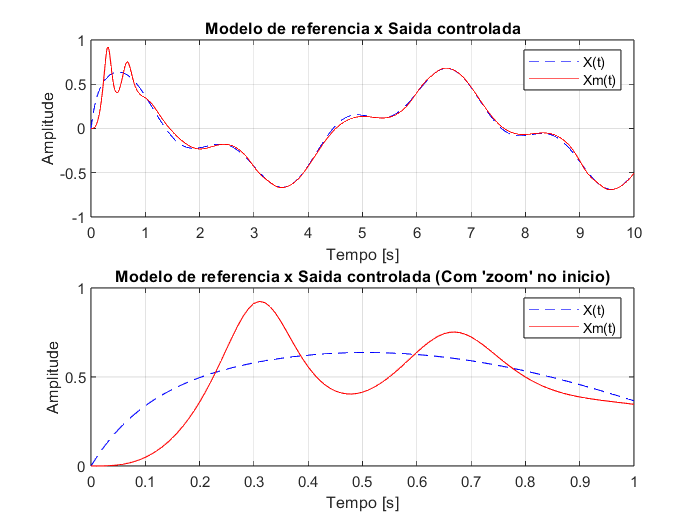


%Posição 
figure
hold on
subplot(2,1,1)
plot(t, xm,'b--' ,t,x,'r');
title("Modelo de referencia x Saida controlada");
xlabel("Tempo [s]");
ylabel("Amplitude");
legend('X(t)','Xm(t)')
grid on

subplot(2,1,2)
plot(t, xm,'b--' ,t,x,'r');
title("Modelo de referencia x Saida controlada (Com 'zoom' no inicio)");
xlabel("Tempo [s]");
ylabel("Amplitude");
xlim([0 1])
legend('X(t)','Xm(t)')
grid on

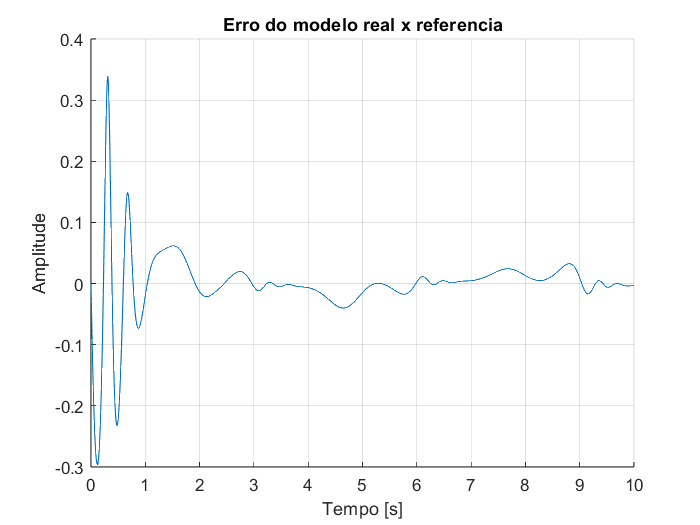


% Erro
figure
hold on
plot(t, e);
title("Erro do modelo real x referencia");
xlabel("Tempo [s]");
ylabel("Amplitude");
grid on

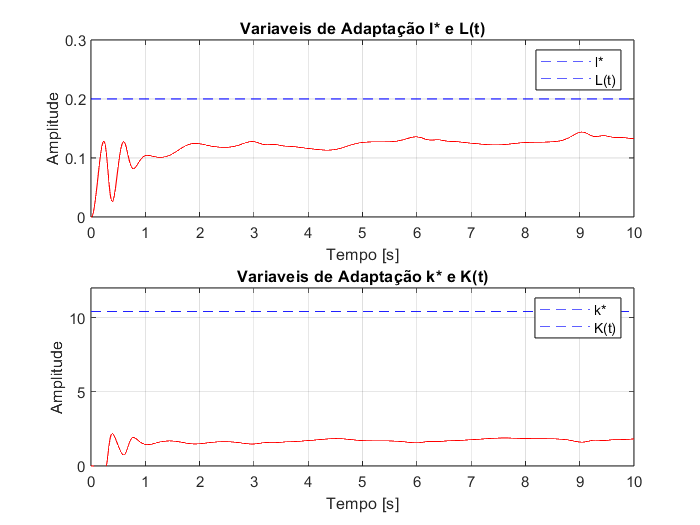



% Variaveis de adaptação
figure
subplot(2,1,1)
plot(t, lponto,'b--' ,t,L,'r');
title("Variaveis de Adaptação l* e L(t)");
xlabel("Tempo [s]");
ylabel("Amplitude");
ylim([0 0.3]);
legend('l*','L(t)');
grid on

subplot(2,1,2)
plot(t, kponto,'b--' ,t,K,'r');
title("Variaveis de Adaptação k* e K(t)");
xlabel("Tempo [s]");
ylabel("Amplitude");
ylim([0 12]);
legend('k*','K(t)');
grid on